10.26

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
Td = 0.01;
pid.Kp = 15;
pid.Ki = 280;
pid.Kd = 0.21;
umax = 6;
Ts = 0.005;
r.A = 1;
r.t = 0.1;

open_system("ex3_sim1m")

Kawu = 0;
set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "1.5")
sim("ex3_sim1m")

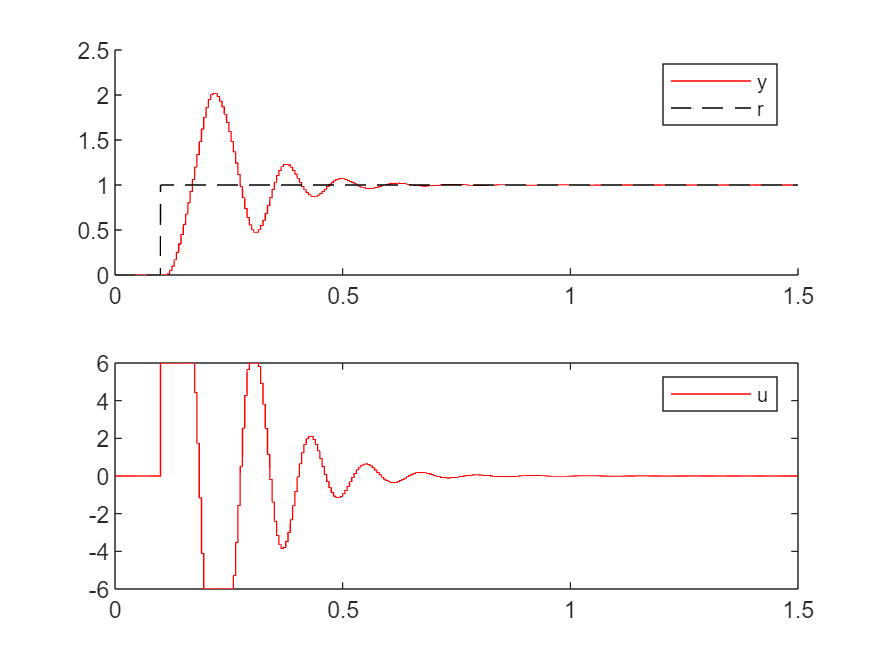

close all
figure(1)
subplot(2, 1, 1)
hold on
plot(sim1_res.time, sim1_res.signals(1).values, "r")
plot(sim1_res.time, sim1_res.signals(2).values, "k--")
legend("y", "r")
subplot(2, 1, 2)
plot(sim1_res.time, sim1_res.signals(3).values, "r")
legend("u")

Kawu = 50;
set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "1.5")
sim("ex3_sim1m")

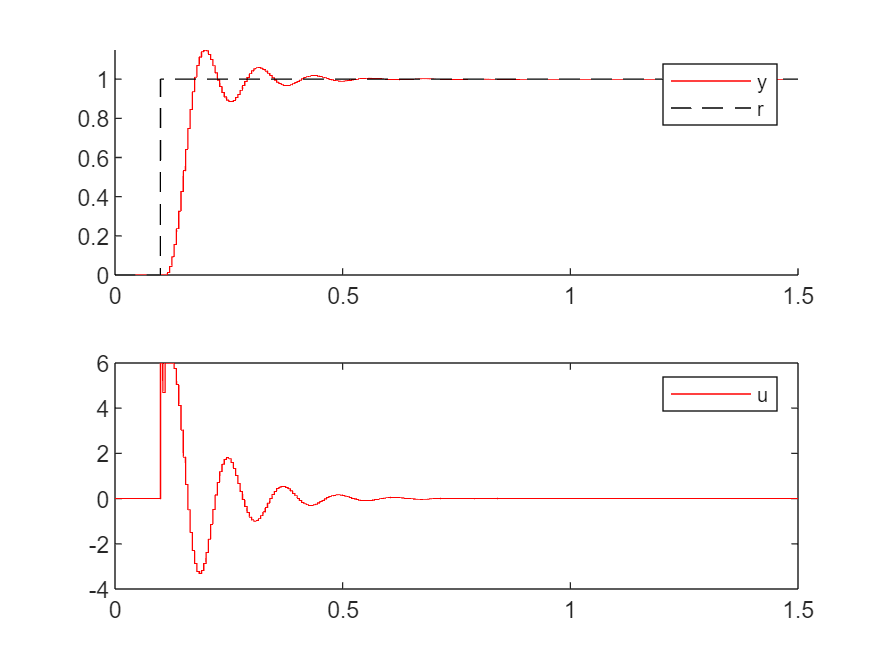

close all
figure(2)
subplot(2, 1, 1)
hold on
plot(sim2_res.time, sim2_res.signals(1).values, "r")
plot(sim2_res.time, sim2_res.signals(2).values, "k--")
legend("y", "r")
subplot(2, 1, 2)
plot(sim2_res.time, sim2_res.signals(3).values, "r")
legend("u")

10.42